## Ejercicio 1 (1.5 puntos). Dado el sistema representado por el diagrama de bloques de la figura, en el que el controlador es un control P:

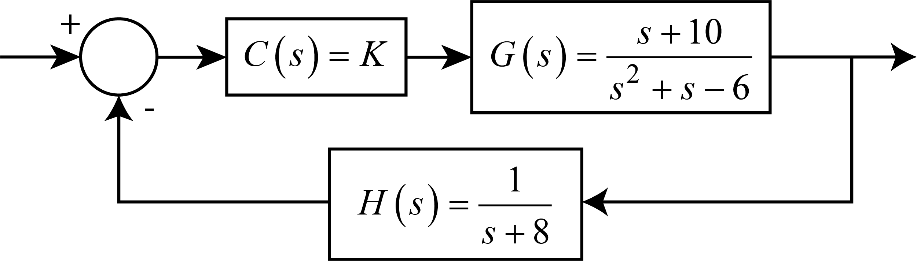

a) ¿Existe algún rango de valores para el controlador que hacen que el sistema se vuelva inestable? (0.25 ptos)

Para saber que valores del controlador hacen el sistema inestable, primero hay que definir las funciones del sistema.

% Defino el sistema
G = tf([1 10], [1 1 -6])

G =
 
    s + 10
  -----------
  s^2 + s - 6
 
Continuous-time transfer function.
Model Properties


H = tf(1,[1 8])

H =
 
    1
  -----
  s + 8
 
Continuous-time transfer function.
Model Properties


Luego, usamos rlocus para mostrar el lugar de las raices, y observamos que hay 2 valores de K para los que el sistema es inestable.

rlocus(G*H)
ylim([-9 9])

Con rlocfind encontramos cada uno de esos valores.

[K1, PolosLC] = rlocfind(G*H) % K es aprox. 66.7

Select a point in the graphics window


selected_point = 0.0035 - 8.2938i

K1 = 66.7437

PolosLC =   -9.0050 + 0.0000i
   0.0025 + 8.2939i
   0.0025 - 8.2939i


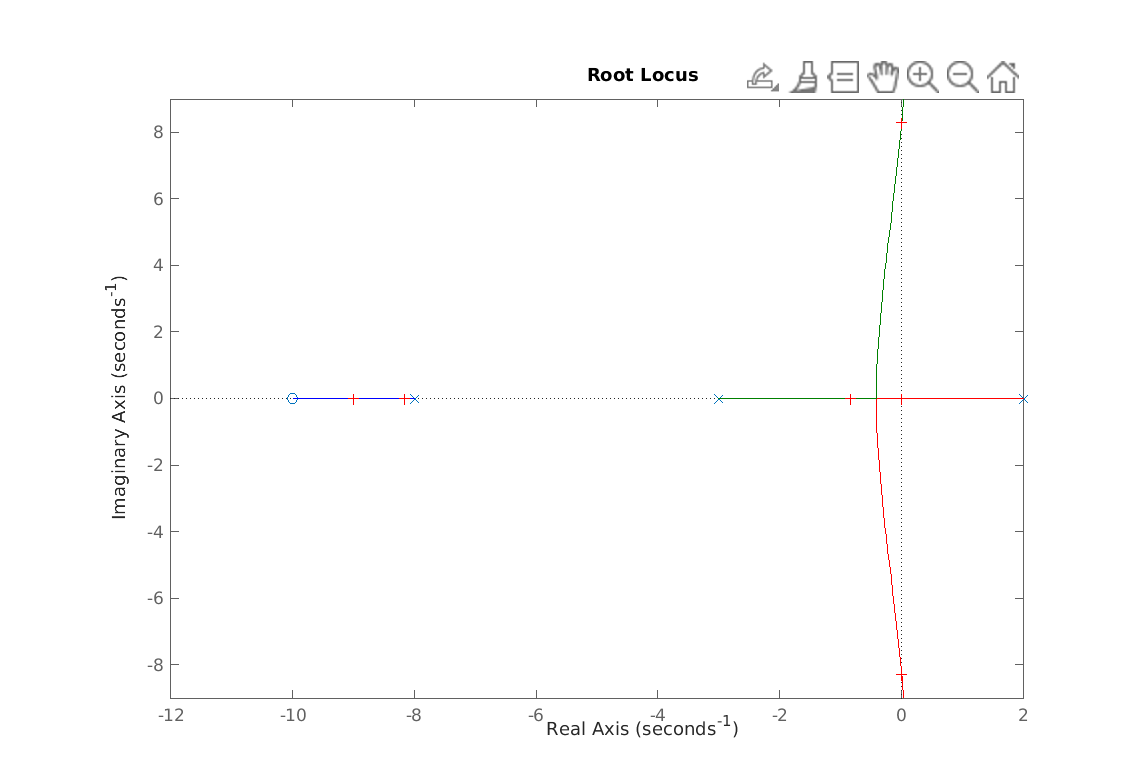

Select a point in the graphics window


selected_point = 0.0035 - 0.0601i

K2 = 4.8008

PolosLC =    -8.1674
   -0.8314
   -0.0011


[K2, PolosLC] = rlocfind(G*H) % K es aprox. 4.8

Luego para K < 4.8 y K > 66.7 el sistema es inestable.

b) ¿Cuál sería el valor del controlador que consigue un comportamiento críticamete amortiguado? (0.25 ptos)

Para conseguir un comportamiento críticamete amortiguado los 2 polos dominantes deben coincidir. Para conseguir esto volvemos a usar rlocfind para encontrar el valor de K.

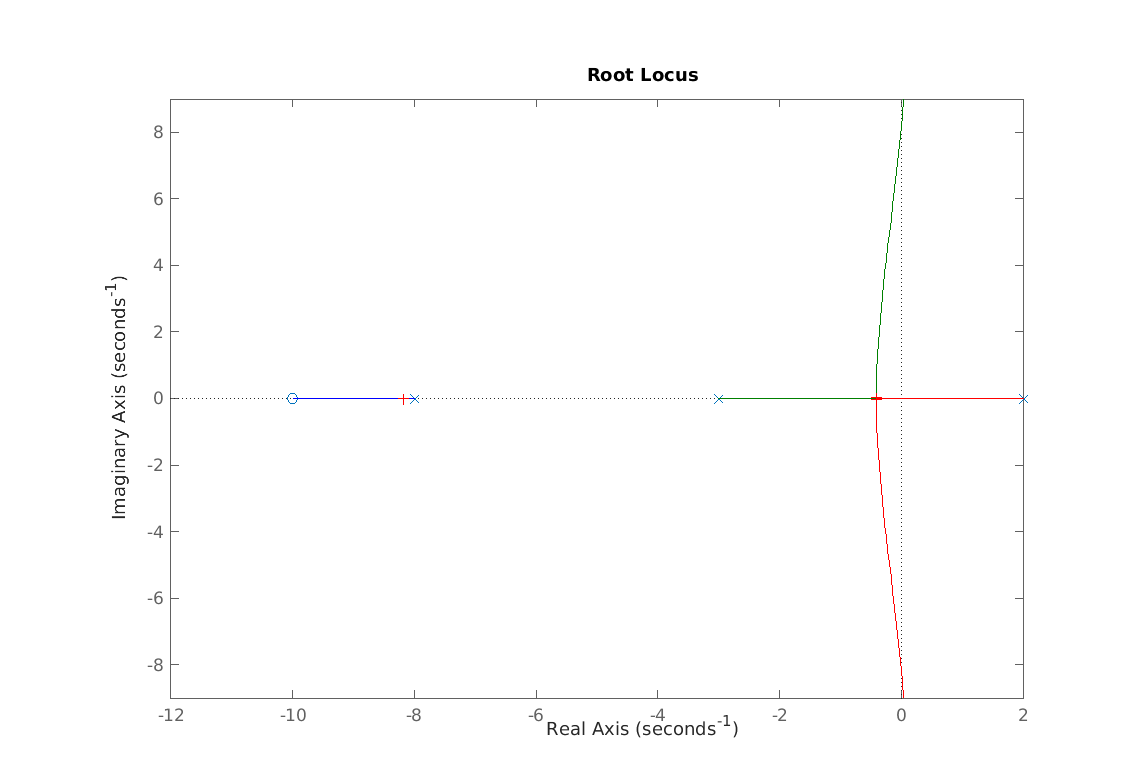

Select a point in the graphics window


selected_point = -0.4073 + 0.0301i

Kc = 4.9409

PolosLC =   -8.1717 + 0.0000i
  -0.4141 + 0.0293i
  -0.4141 - 0.0293i


% Usamos rlocfind para encontrar el valor de K para que sea críticamete amortiguado
rlocus(G*H)
ylim([-9 9])
[Kc, PolosLC] = rlocfind(G*H) % K es aprox. 4.94

Luego para K == 4.94 el sistema es críticamete amortiguado.

c) Se quiere que el sistema se comporte con un factor de amortiguamiento 𝜁 = 0.75 y una frecuencia natural 𝜔𝑛 = 6 . ¿Es posible hacer que el sistema se comporte con estas características, cómo se haría? Justifique su respuesta (0.5 ptos)

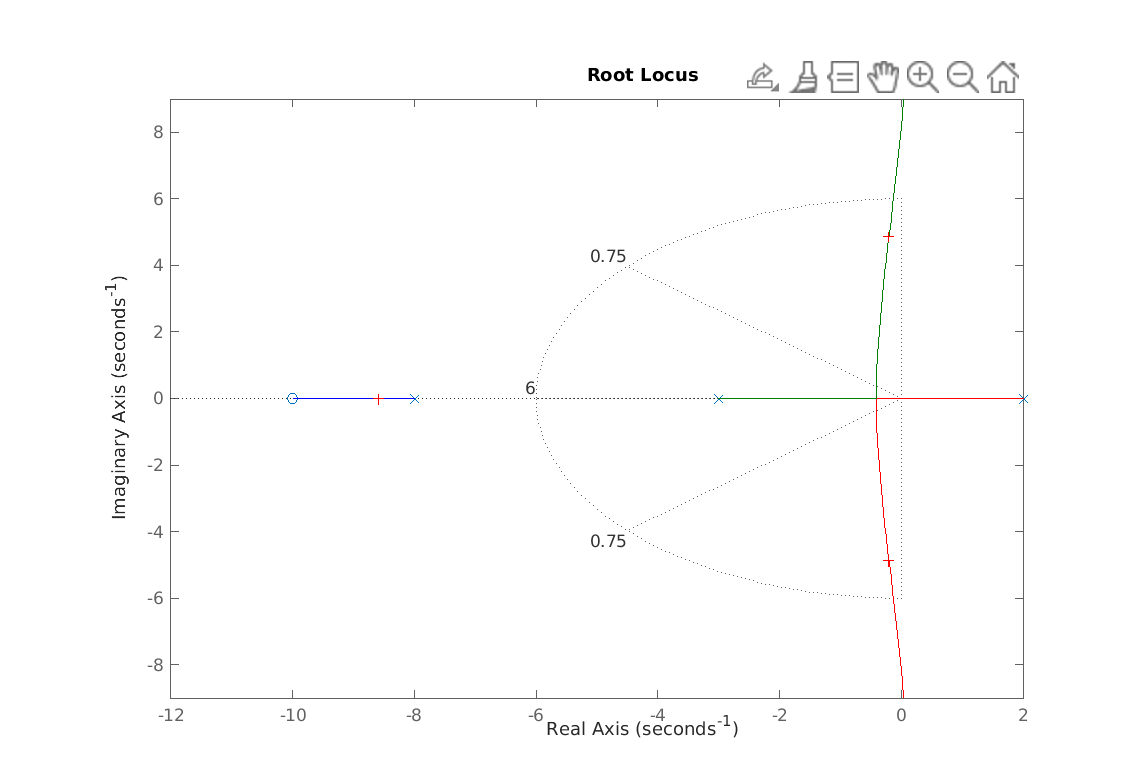

Select a point in the graphics window


selected_point = -4.4824 + 3.9666i

k_ambos = 25.1072

rlocus(G*H);
chi = 0.75;
wn = 6;
sgrid(chi, wn);
ylim([-9 9])
k_ambos=rlocfind(G*H)

Como se puede ver en el LDR no hay ningun punto posible que cruce en la interseccion del grid de 𝜁 = 0.75 y de 𝜔𝑛 = 6, por lo tanto para lograr este comportamiento habria que añadir polos o ceros con algun PID para que el nuevo LDR pasara por esa interseccion.

d) ¿Cuál es el controlador que consigue una frecuencia natural de 1.5rad/s? Represente el comportamiento del sistema con este controlador ante una entrada escalón. (0.5ptos)

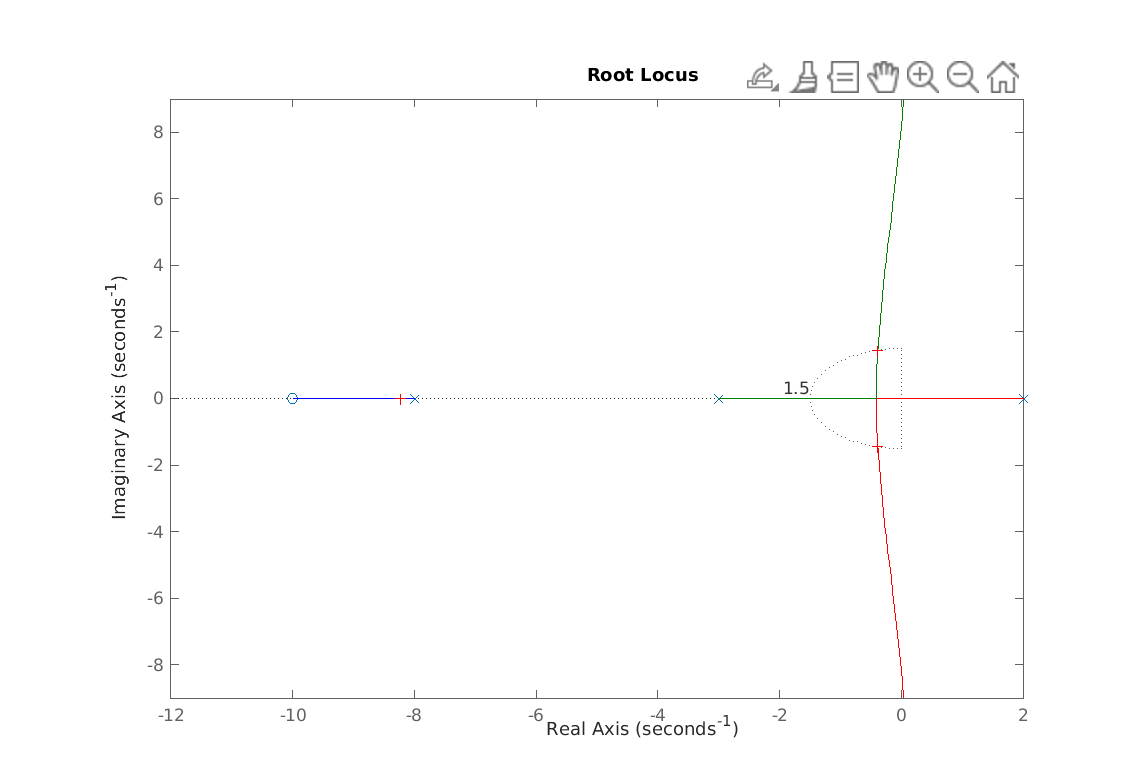

Select a point in the graphics window


selected_point = -0.3908 + 1.4424i

k_wn15 = 6.6350

rlocus(G*H);
wn = 1.5;
sgrid([], wn);
ylim([-9 9])
k_wn15=rlocfind(G*H)

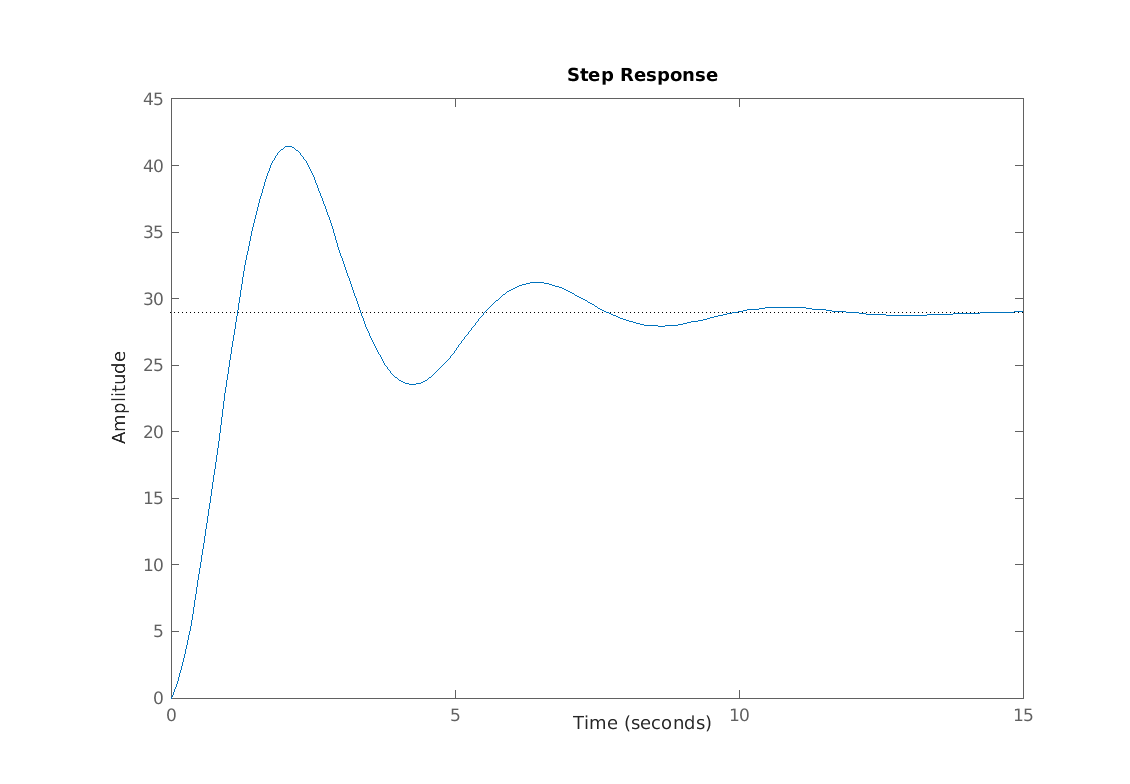


step(feedback(k_wn15*G,H))